# Introduction to MRI and Structural MRI (sMRI)

## What is MRI?

Magnetic Resonance Imaging(MRI) is a non-invasive imaging technique that captures detailed images of the brain's structure. 

These images are particularly beneficial in patients with suspected neurological or musculoskeletal pathology. 

MRIs work like this: 

- The atoms in your body (predominantly hydrogen) have magnetic properties that can respond to strong magnetic fields and radio waves from the MRI machine to create images. 

- The strength of this signal depends on the type of tissues (fat, muscle, water) that the hydrogen ion is in. 

- The MRI machine can then capture differences in how tissues respond, like grey matter, white matter, and cerebrospinal fluid (CSF). These differences are shown as varying levels of brightness in the images. 

*If you are interested in the physics behind the MRIs, you will have subsequent lectures in Module 6 - Neuroimaging to learn in details. :)*

What are the benefits of using MRI? 

- There is a good tissue contrast

- There is no need to inject  a contrast material (unlike PET imaging)

What are some disadvantages? 

- Relatively slow to process

- Sensitive to motion artifacts (artifacts: visual anomaly that are not present in the orginal object)

- Expensive 

## How to load a brain image in MATLAB? 

Let's first try loading an image in MATLAB - brain images are often in NIfTI format. 

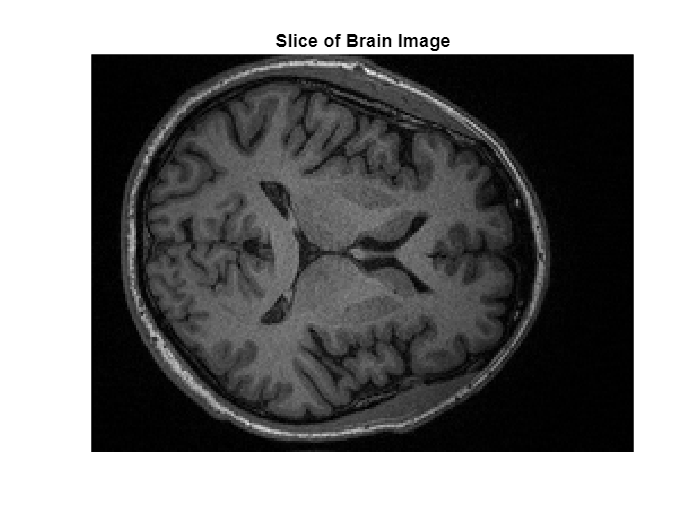

% Load a brain image
addpath('Brain Images')
filename = 'RawBrain.nii';
brainImage = niftiread(filename);

% Let's visualise a thin slice through the brain
slice = brainImage(:,:,168); % This shows the 168th slice in a 2D view
imshow(slice, [], 'InitialMagnification', 'fit');
title('Slice of Brain Image')

Can you guess which plane this brain is on? This is the axial (horizontal) plane of the brain. 

You can see the interhemispheric fissue, lateral ventricle, as well as the head of caudate nucleus, and parts of basal ganglia in the image. 

What if I want to see the saggital plane, perhaps the 100th slice in a 2D view, how would I view it?

% Write your code here

Nice! Do you see image like this? 

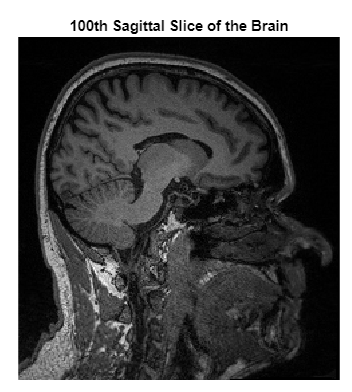

If you notice your brain scan is rotated, you can add` rot90(sagittalSlice, 1) `to your image, and it will produce the above image. 

## What information can you get from an MRI image? 

As stated earlier, different tissues can be distinguished through the brightness of the scan. But how can one analyse a MRI scan with brightness (intensity) differences?

Raw MRI images can have wide intensity ranges, often from **0** to several **thousand arbitrary units**. (This will be different after the image pre-processing steps, often resacled to standard intensity ranges, such as 0 to 255 or 0 to 1). 

For instance, our raw brain image has a range of:

% Check the minimum and maximum intensity values
minIntensity = min(brainImage(:));
maxIntensity = max(brainImage(:));

fprintf('The intensity range of the MRI image is: %d to %d\n', minIntensity, maxIntensity);

Should we first check the intensity (the number representing the brightness) of a specific coordinate?

% Get intensity of a randomly chosen coordinate 
intensity_a = brainImage(76,154,150);
fprintf('The intensity of the selected coordinates is: %d\n', intensity_a);

What about the coordinate` (25, 25, 159)`? 

% Write your code here

The intensity values represent tissue properties, and their appearance depends on how much signal was received from that specific tissue during the scan. 

In general for anatomical (T1) scans:

**Higher Intensity (brighter areas):**

- Higher intensity often means that the tissue is reflecting or emitting a stronger signal

- Tissues that typically have higher intensity include: White matter, fatty tissues

**Lower intensity (darker areas):**

- Lower intensity means that the tissue produces a weaker signal, appearing darker on the MRI scan

- Tissues that often have lower intensity are: Grey matter, CSF, Bone

It is **CRUCIAL** to note that for different scans, the brightness of the tissues will differ.

There are **two main ways** we can analyse these brightness differences:

1) Voxel-Based Analysis

- A **voxel **is the smallest 3D block in an MRI image, like a 3D pixel. Each voxel has an intensity value, which represents the brightness at that point in the brain.

- **Voxel-based analysis **looks at every voxel in the brain individually. This is useful if you don't want to be biased by different known regions in the brain, and would rather examine detailed changes across the whole brain.

- Simply speaking, you are just zooming in and looking at every small point in the brain to check its brightness. 

2) ROI-Based Analysis

- An **ROI** (Region of Interest) is a larger, pre-defined area of the brain that we want to study. It often links to the anatomical label within the brain - such as motor cortex or hippocampus. 

- **ROI-based analysis** averages the intensity of all the voxels within that region to give us one value for that whole area. This is helpful if we want to look at a specific region only. 

- Simply speaking, this is the average brightness of a section you are interested in. You can compare this to another section and see which is "brighter" or "darker". 

### What are voxels, and how do we use this?

Now we know that a voxel is the smallest unit in the 3D MRI image. 

Here are some additional details to know about **VOXEL-BASED ANALYSIS (VBA)**:

- Voxel size depends on the resolution of the MRI scan. Smaller voxels: more detailed images

- **Voxel-Based Morphometry (VBM)**: A common voxel-level analysis technique is VBM, which measures differences in local brain anatomy. You can compare voxel intensities between groups (e.g., healthy controls vs. PD patients) to see where the brain structure differs

- Since VBA doesn't focus on specific regions unlike ROI, this type of analysis examines the entire brain voxel by voxel

- VBA gives a highly detailed look at the brain (and thus, can be computationally expensive to analyse) 

Since the voxel size is so heavily reliant on the resolution of the MRI scan, we should first understand voxel dimensions in MRI. This determines the quality of the data, and how much detail you can see in the brain's structure. 

Let's see the voxel dimensions in our brain image: 

% Check voxel dimensions

The intensity range of the MRI image is: 0 to 1352


info = niftiinfo(filename);
voxelDimensions = info.PixelDimensions;  % Size of voxels in mm
fprintf('Voxel dimensions: %.2f x %.2f x %.2f mm\n', voxelDimensions);

A typical MRI voxel is 1mm x 1mm x 1mm, but it could also be larger, such as 2mm x 2mm x 2mm. 

- Smaller voxels = higher spatial resolution.

- **Voxel size** also impacts how well you can isolate and analyse specific brain regions. 

- Voxel size also affects **signal-to-noise ratio (SNR)** - larger voxels can capture signals from a larger area, which increases both the signal and potential noise.

### What are ROIs (Regions of Interest)?

As stated earlier, an ROI is a specific part of the brain that you want to study. For instance, if you are interested in movement, you might want to focus on the motor cortex. 

Let's overlay the motor cortex atlas on our brain image.

addpath("Brain Images")


The intensity of the selected coordinates is: 305


% Load the mask to overlay on the brain image
roiMask = niftiread('aparc+aseg.nii');

% ROI values for the precentral gyrus (motor cortex)
roiValueLH = 1024;
roiValueRH = 2024;

% Extract the left and right motor cortex ROIs
motorCortexLH = roiMask == roiValueLH;
motorCortexRH = roiMask == roiValueRH;

% Applying to our brain image
procbrainImage = niftiread('brain.nii');
motorCortexImageLH = procbrainImage .* cast(motorCortexLH, class(procbrainImage));
motorCortexImageRH = procbrainImage .* cast(motorCortexRH, class(procbrainImage));

% Slice to display
sliceNum = 80;

% Creating a figure
figure;

% Left Hemisphere Motor Cortex with Brain in Grayscale
subplot(1, 2, 1);

brainSliceLH = rot90(procbrainImage(:,:,sliceNum), -1);  
imshow(brainSliceLH, [], 'InitialMagnification', 'fit');
colormap('gray');
hold on;


Voxel dimensions: 1.00 x 1.00 x 1.00 mm


% Overlay motor cortex (LH) in red, rotated 90 degrees clockwise
redMaskLH = cat(3, ones(size(motorCortexLH(:,:,sliceNum))), zeros(size(motorCortexLH(:,:,sliceNum))), zeros(size(motorCortexLH(:,:,sliceNum))));
redMaskLH = rot90(redMaskLH, -1);
motorCortexLH_rotated = rot90(motorCortexLH(:,:,sliceNum), -1);
h = imshow(redMaskLH);
set(h, 'AlphaData', motorCortexLH_rotated * 0.5); % Just adjusting the transparency
title('Left Hemisphere Motor Cortex');

% Right Hemisphere Motor Cortex with Brain in Grayscale
subplot(1, 2, 2);

brainSliceRH = rot90(procbrainImage(:,:,sliceNum), -1);  
imshow(brainSliceRH, [], 'InitialMagnification', 'fit');
colormap('gray');
hold on;

% Overlay motor cortex (RH) in red, rotated 90 degrees clockwise
redMaskRH = cat(3, ones(size(motorCortexRH(:,:,sliceNum))), zeros(size(motorCortexRH(:,:,sliceNum))), zeros(size(motorCortexRH(:,:,sliceNum))));
redMaskRH = rot90(redMaskRH, -1);
motorCortexRH_rotated = rot90(motorCortexRH(:,:,sliceNum), -1);
h = imshow(redMaskRH);
set(h, 'AlphaData', motorCortexRH_rotated * 0.5);
title('Right Hemisphere Motor Cortex');

 *Please don't be frightened by the amount of code displayed here. You will not be asked to do this - it's for demonstration purposes.*

Here, we have motor cortex overalyed on our brain image. This can be later used to calculate morphological differences (i.e., surface area, volume, thickness) 

### Detecting MRI artifacts

As you may have noticed in the previous section, the brain image loaded is lacking non-brain tissues, such as the **skull, scalp, **and **CSF.** This process is commonly called **skull stripping**. This processing along with further preprocessing steps allows you to analyse essential brain tissues, such as grey matter and white matter. 

In order to accurately process your brain scan, you need to make sure the raw MRI scan is properly captured. In the very beginning of this workshop, I have shared that one of the disadvantages of MRI imaging is its sensitivity towards motion artificats. **Artifacts** is often caused by patient movement (motion artifact), and this can interfere with data interpretation and analysis. Of course, not all artifacts are caused by the patient movement and it can be caused by the scanner malfunctions, or other susceptibilities.

Here is are some examples of MRI artifact: 

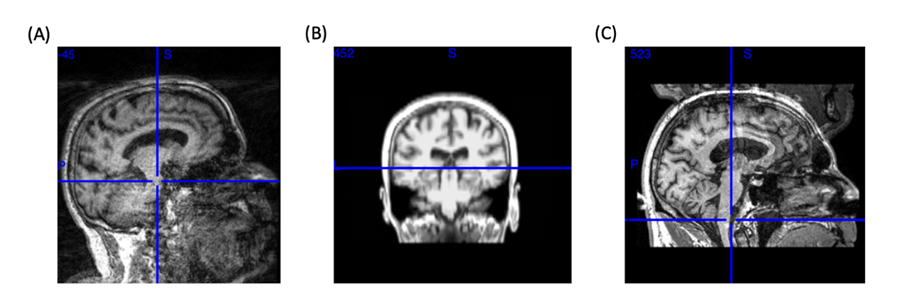

**A) Gibbs Ringing, B) Susceptibility artifact, C) Ghost + Motion Artifact**

In research, **reproducibility** is critical. If your data contains artifacts that are not identified or corrected, they can skew results in a way that makes it hard for others to replicate your findings. So please handle artifacts before starting any processing with the images. This can easily be done via visual inspection! 

## How to preprocess your MRI scans

Did you know when dealing with MRI images, most of your time is dedicated to preprocess them rather than the analysis itself? It is an extensive procedure with series of steps to segment the brain, extract key ROIs, and generate cortical/ subcortical surface models. 

The goal in this section is to understand the general steps of the **Freesurfer **`recon-all` pipeline for anatomical analysis. 

Freesurfer is a software suite for processing and analysing brain MRI images. It is primarily used for **cortical and subcortical segmentation** and creating detailed surface models of the brain T1-weighted scans.

**What does it do? **

- Performs skull stripping to remove non-brain tissues (scalp, skull).

- Segments brain regions in **grey matter, white matter, and CSF**. 

- Reconstructs the brain's **cortical surface**. 

- Provides detialed information about cortical thickness, surface area, and subcortical volumes.

Now, for the sake of simplicity, we will be only dealing with cortical information in this workshop. It is important to note that there are additional pipelines you can utilise along with the Freesurfer to segment subcortical surface if needed. 

### Motion Correction

For the sake of demonstration, the image below is an altered imaged from the original raw scan I showed you earlier.

sliceNum = 170;

shiftedImage = circshift(brainImage(:,:,sliceNum), [23, 20]); 
rotatedImage = imrotate(shiftedImage, 2, 'bilinear', 'crop'); 

figure;
imshow(rotatedImage, [], 'InitialMagnification', 'fit');
title('Misaligned (Shifted and Rotated) Brain Image Slice');
colormap('gray');

What Freesurfer initially does is motion correction. It ensures that any motion artifacts are corrected before proceeding with other steps, such as intensity normalisation, skull stripping, and segmentation. 

This is a very simple way of demonstrating how motion correction works:

fixedImage = brainImage(:,:,sliceNum);  
movingImage = rotatedImage; 

[optimizer, metric] = imregconfig('monomodal');
tform = imregtform(movingImage, fixedImage, 'similarity', optimizer, metric);

registeredImage = imwarp(movingImage, tform, 'OutputView', imref2d(size(fixedImage)));

figure;
imshowpair(fixedImage, registeredImage, 'montage');
title('Original vs Corrected Image After Motion Correction (Translation + Rotation)');

The left image is an orginal scan you got to play with earlier, whereas the right image is the corrected image. 

It is essential to ensure that the entire brain scan is correctly aligned before any other preprocessing steps. If motion artifacts are not corrected, they can distort brain structures, leading to **inacurrate segmentations** and cortical surface reconstructions. 

PLEASE note that the script above works on a **single 2D slice **of the MRI image. It uses MATLAB's `imregtform` function to correct shifts and rotations within that single slice. However, Freesurfer can perform motion correction on 3D volumes, and considers the entire brain MRI scan (all slices) when realigning the image. 

### Intensity Normalisation and Skull Stripping

Intensity normalisation is a step that adjusts the brightness (intensity) of different tissues in an MRI image to ensure cosistent contrast across the brain. This is especially important for later steps like **segmentation,** where different tissues (like grey matter, white matter, and CSF) need to be accurately distinguished.

Skull stripping is the process of removing non-brain tissues (like the skull, scalp, and sometimes CSF) from the MRI scan. This is done to isolate the brain from surrouding structures, which might interfere with further analysis. 

Here are two figures illustrating before normalising and skull stripping, and after: 

figure;
for sliceNum = 69
    coronalSlice = squeeze(brainImage(:,sliceNum,:));
    coronalSlice = rot90(coronalSlice, 1);
    subplot(1, 2, 1);
    imshow(coronalSlice, [], 'InitialMagnification', 'fit');
    title('Orignal MRI slice');
    colormap('gray');
end

subplot(1, 2, 2);
procbrainImageSlice = procbrainImage(:,:,76);
procbrainImageSlice = rot90(procbrainImageSlice, 3);
imshow(procbrainImageSlice, [], 'InitialMagnification', 'fit');
title('Normalised and Skull-Stripped MRI Slice');
colormap('gray');

Now you can see how the 1) normalisation makes it easier to distinguish different brain tissues by removing variations caused by the MRI machine, 2) stripping removed unnecessary tissues that could later interfere with further analysis. 

Moving forward, Freesurfer can:

- **Tissue segmentation**: Segmenting the brain into different tissue types. specifically identifying grey and white matter.

- **Subcortical Structure segmentation**: Identifying and labelling subcortical structures like thalamus, putamen, hippocampus, and more.

- **Cortical surface reconstrution**: Building a mesh that represents the boundary between grey and white matter to calculate cortical thickness, and surface area.

- **Cortical parcellation**: Dividing brain's cortex into anatomical regions based on predefined atlases (Destrieux atlas). This allows ROIs to be extracted

- **Surface-based registration to standard space**: Aligning each subject's cortical surface to a common template (e.g., fsaverage) so you can easily undergo group-level analysis.

And these steps allows **Final Outputs for T1 Image Data:**

- Cortical Thickness: Measure of the thickness of the cortex in various brain regions

- Volumes: Volumetric measurements

- Surface area

## Structural MRI Data Analysis

Now, using the preliminary understanding of structural MRI, we can start the data analysis!

For the simplicity of this workshop, we will be only dealing with cortical regions today. Let's say I'm interested in exploring one of the cross-sectional subjects. There are many** stats files** that are extracted among Freesurfer outputs you can use for the structural analysis. 

You can first try opening one of the stats files as a **text file** and see how they are organised. 

Among them, we will first try loading the **brainvol.stats** file that contains all the summary volumetric data, without any specific ROIs chosen. 

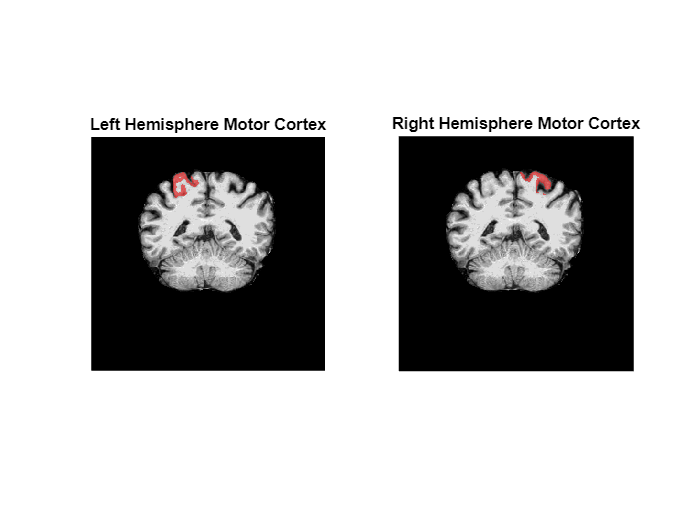

addpath("Brain Images\")
filename = 'brainvol.stats';
fid = fopen(filename, 'r');


% Initialize storage for extracted information
regionNames = {};
volumes = [];

% Read the file line by line
while ~feof(fid)
    tline = fgetl(fid);
    if startsWith(tline, '# Measure')
        % Split the line into components
        tokens = strsplit(tline, ',');
        
        % Extract the region name (second part) and volume (fourth part)
        regionNames{end+1} = strtrim(tokens{2});  % Region name
        volumes(end+1) = str2double(strtrim(tokens{4}));  % Volume in mm³
    end
end
fclose(fid);

By running this script, you will now be able to visualise the data. This is esentially loading the data based on how the Freesurfer output is formatted as.

### Visualising Volumetric Data

Now, since we have loaded the data, we can **visualise** it and see the summary scores of overall brain regional volumes. 

figure;
bar(volumes);
set(gca, 'XTick', 1:length(regionNames), 'XTickLabel', regionNames);
xtickangle(45); % Rotate x-axis labels to fit more text
xlabel('Brain Regions');
ylabel('Volume (mm³)');
title('Brain Region Volumes');

If I want to extract a specific regional volume, like the **TotalGrayVol**, I could: 

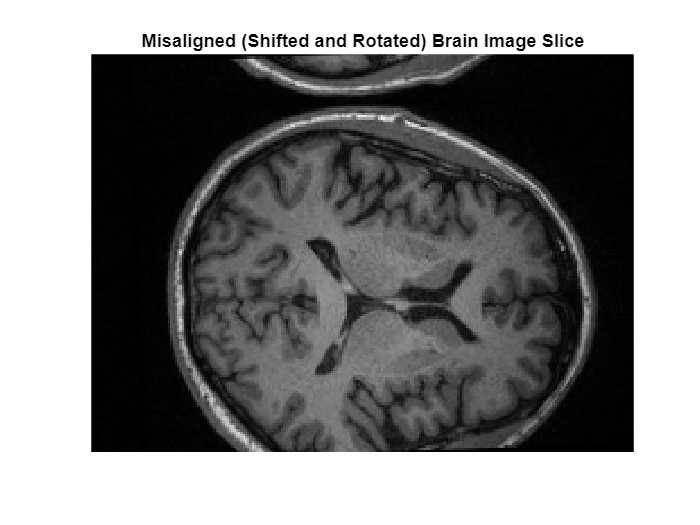

targetRegion = 'TotalGrayVol'; 


% Find the index of the target region in the regionNames array
regionIndex = find(strcmp(regionNames, targetRegion));

% Check if the region was found and display the corresponding volume
if ~isempty(regionIndex)
    volumeOfInterest = volumes(regionIndex);
    fprintf('The volume of %s is %.2f mm³.\n', targetRegion, volumeOfInterest);
else
    fprintf('Region "%s" not found in the loaded data.\n', targetRegion);
end

What if I want to know **Cerebral White Matter** volume? what is that? 

% Write your code here

Great! the volume should be 473721.00mm3. 

**Now can you load a left hemisphere cortical data? **

(hint1: the file is called lh.aparc.DKTatlas.stats)

(hint2: the storage for data is pre-written out for you)

(hint3: the `if statsWith(tline, '#'); `you want to skip that information as that's just header or comment lines )

(hint 4: `tokens` variable is now split per tline not `tline, ','`)

(hint 5: you want to disregard any tokens with lengths smaller than 10, as that's not a valid data row)

(hint 6: the storage order here should be the order of tokens as well {1}, {2}, ... {n})

(hint 7: all the variables apart from the name should be numerical values, thus `str2double`)

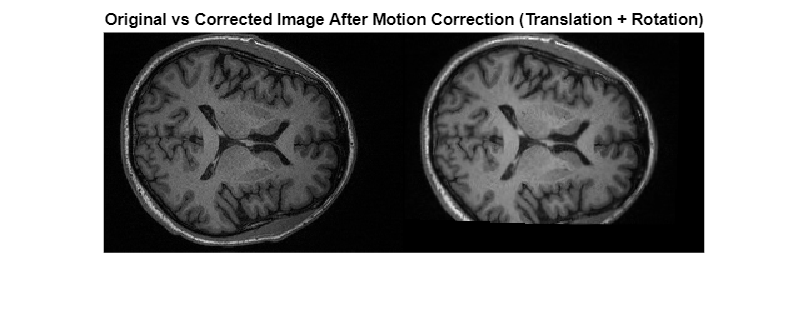

addpath("Brain Images\")
filename = 'lh.aparc.DKTatlas.stats';
fid = fopen(filename, 'r');


% Initialising storage for extracted information
structNames = {};
lhnumVertices = [];
lhsurfArea = [];
lhgrayVol = [];
lhthickAvg = [];
lhthickStd = [];

% Write your While loop here

now please visualise the grey volume per region:

(hint: Freesurfer was developed in American English so grey vol => gray vol) 

% Write your code here

What's the volume of postcentral gyrus? 

% Write your code here

Cool! Now let's learn how to **compare between left and right hemispheres** for this subject. 

First load rh data: 

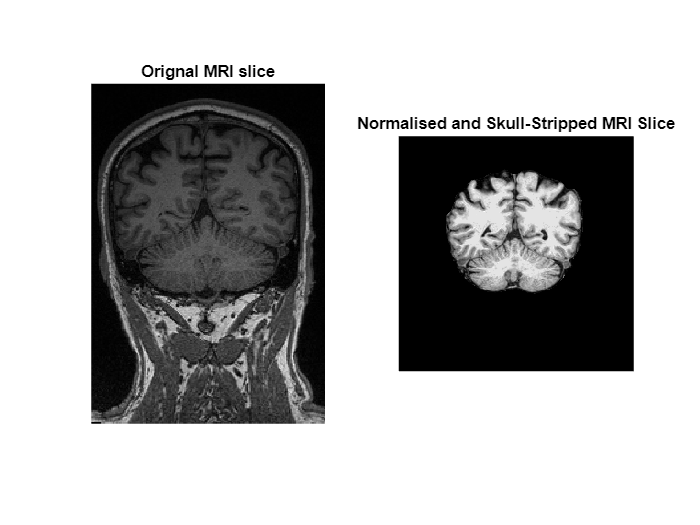

addpath("Brain Images\")
filename = 'rh.aparc.DKTatlas.stats';
fid = fopen(filename, 'r');

% Initialize storage for extracted information
structNames = {};
rhnumVertices = [];
rhsurfArea = [];
rhgrayVol = [];
rhthickAvg = [];
rhthickStd = [];

% Read the file line by line
while ~feof(fid)
    tline = fgetl(fid);
    

    % Skip lines that start with '#' (header/comment lines)
    if startsWith(tline, '#')
        continue;  % Skip this line
    end
    
    % Split the line into components
    tokens = strsplit(tline);
    
    % Only process lines that have at least 10 tokens (data rows)
    if length(tokens) >= 10
        structNames{end+1} = tokens{1};                  % Structure name
        rhnumVertices(end+1) = str2double(tokens{2});      % Number of vertices
        rhsurfArea(end+1) = str2double(tokens{3});         % Surface area (mm²)
        rhgrayVol(end+1) = str2double(tokens{4});          % Gray matter volume (mm³)
        rhthickAvg(end+1) = str2double(tokens{5});         % Average thickness (mm)
        rhthickStd(end+1) = str2double(tokens{6});         % Thickness standard deviation (mm)
    end
end

fclose(fid);

Let's first load RH grey volumes to see we have loaded the data correctly. 

% Write your code here

How different are they? Let's visualise it.

% Combine LH and RH data into a matrix (2 rows: 1st row for LH, 2nd row for RH)
grayVolCombined = [lhgrayVol; rhgrayVol]; 

figure;
set(gcf, 'Position', [100, 100, 1200, 600]);
bar(grayVolCombined', 'grouped');  % Transpose the matrix so that each region has 2 bars (LH, RH)

set(gca, 'XTick', 1:length(structNames), 'XTickLabel', structNames);
xtickangle(45); % Rotate x-axis labels to fit more text

% Add labels and title
xlabel('Cortical Regions');
ylabel('Volume (mm³)');
title('Cortical Grey Matter Volumes (LH vs RH)');

% Add a legend to indicate which color represents LH and RH
legend({'LH', 'RH'}, 'Location', 'best');

Cool! This individual seems to have some variation in their cortical volumes between left and right hemisphere. This is completely normal.

But what about overall differences? Which hemisphere do you think this indivdual have larger volume? 

In this case, we are simply comparing all the cortical regions in this individual so we just have to add up all the grey vol per hemisphere and see which ones bigger. 

lhTotalGrayVol = sum(lhgrayVol);
rhTotalGrayVol = sum(rhgrayVol);

fprintf('Total LH Grey Matter Volume: %.2f mm³\n', lhTotalGrayVol);
fprintf('Total RH Grey Matter Volume: %.2f mm³\n', rhTotalGrayVol);

It seems like this person has a bigger LH grey volume. 

What about on average? That individual has PD but is at de novo state. 

I want to see if in general I see bigger LH grey volume in other de novo participants. 

addpath("Brain Images\cs_denovo\")

This is the path where the patient data are stored in. 

Let's first initialise and load storage for grey volumes and see if any of the participant is missing either of the files.

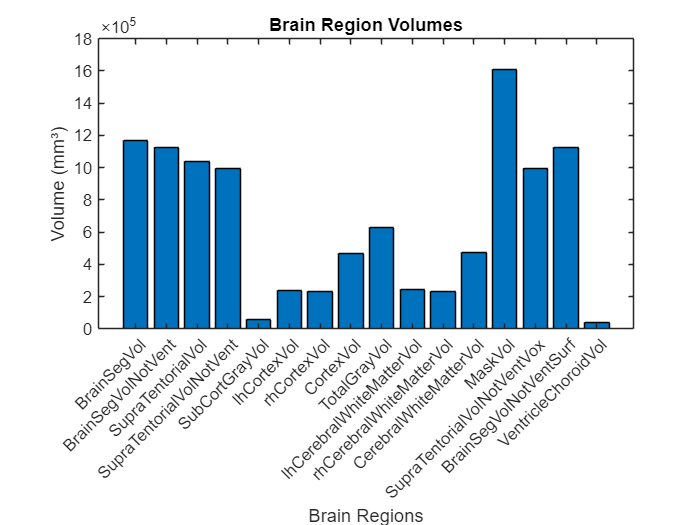

denovo_dir = 'Brain Images\cs_denovo';  

addpath ("Functions\"); %we are implementing the extractGrayVol function for a faster process 

lhGrayVols = [];
rhGrayVols = [];

if ~isfolder(denovo_dir)
    error('Directory %s does not exist.', denovo_dir);
end

participants = dir(denovo_dir);
participants = participants([participants.isdir] & ~ismember({participants.name}, {'.', '..', '.DS_Store'}));  % Filter directories only

for i = 1:length(participants)
    lh_stats_file = fullfile(denovo_dir, participants(i).name, 'lh.aparc.DKTatlas.stats');
    rh_stats_file = fullfile(denovo_dir, participants(i).name, 'rh.aparc.DKTatlas.stats');

The volume of TotalGrayVol is 628787.72 mm³.


    
    if exist(lh_stats_file, 'file') && exist(rh_stats_file, 'file')
        lh_gray_vol = extractGrayVol(lh_stats_file);
        rh_gray_vol = extractGrayVol(rh_stats_file);
        
        lhGrayVols(end+1) = lh_gray_vol;
        rhGrayVols(end+1) = rh_gray_vol;
    else
        fprintf('Stats file missing for participant: %s\n', participants(i).name);
    end
end

if isempty(lhGrayVols) || isempty(rhGrayVols)
    error('No gray volumes loaded. Check if the files exist and the directory structure is correct.');
end

Have they been loaded correctly?

disp(lhGrayVols);
disp(rhGrayVols);

Now, I'm sure as you must have learnt before.. you need to check if you can use parametric or non-parametric testing before running any statistical analysis. 

1) Are they normalised? 

figure;
subplot(1,2,1);
histogram(lhGrayVols);
title('LH Gray Matter Volume Distribution');
xlabel('Volume (mm³)');
ylabel('Frequency');

subplot(1,2,2);
histogram(rhGrayVols);
title('RH Gray Matter Volume Distribution');
xlabel('Volume (mm³)');
ylabel('Frequency');
% Perform Shapiro-Wilk normality testing for LH gray matter volumes
[h_lh, p_lh] = swtest(lhGrayVols);

% Perform Shapiro-Wilk normality testing for RH gray matter volumes
[h_rh, p_rh] = swtest(rhGrayVols);

% Display results
if h_lh == 0
    fprintf('LH gray matter volumes are normally distributed (Shapiro-Wilk, p = %.3f).\n', p_lh);
else
    fprintf('LH gray matter volumes are NOT normally distributed (Shapiro-Wilk, p = %.3f).\n', p_lh);
end

if h_rh == 0
    fprintf('RH gray matter volumes are normally distributed (Shapiro-Wilk, p = %.3f).\n', p_rh);
else
    fprintf('RH gray matter volumes are NOT normally distributed (Shapiro-Wilk, p = %.3f).\n', p_rh);
end

2) Equal variance? 

combinedVols = [lhGrayVols, rhGrayVols]';

group = [ones(size(lhGrayVols)), 2 * ones(size(rhGrayVols))]';

[h, p_val, ci, stats] = vartest2(lhGrayVols, rhGrayVols);

fprintf('F-test for equal variances p-value: %.4f\n', p_val);
if h == 0
    fprintf('The variances are equal between LH and RH (p = %.4f).\n', p_val);
else
    fprintf('The variances are NOT equal between LH and RH (p = %.4f).\n', p_val);
end

3) Independence? 

You'd assume independence in this case between subjects, as it is most likely that the measurements of each participant were collected separately and can't influence each other. 

Based on the information, we should be able to run a parametric testing. 

mean_lhGrayVol = mean(lhGrayVols);
mean_rhGrayVol = mean(rhGrayVols);

fprintf('Average LH Grey Matter Volume: %.2f mm³\n', mean_lhGrayVol);
fprintf('Average RH Grey Matter Volume: %.2f mm³\n', mean_rhGrayVol);

Oh, that's interesting. Is LH grey matter normally bigger than RH at de novo state in PD patients? 

Let's do a paired t-test to compare LH and RH grey matter, as there are LH and RH data per participant: 

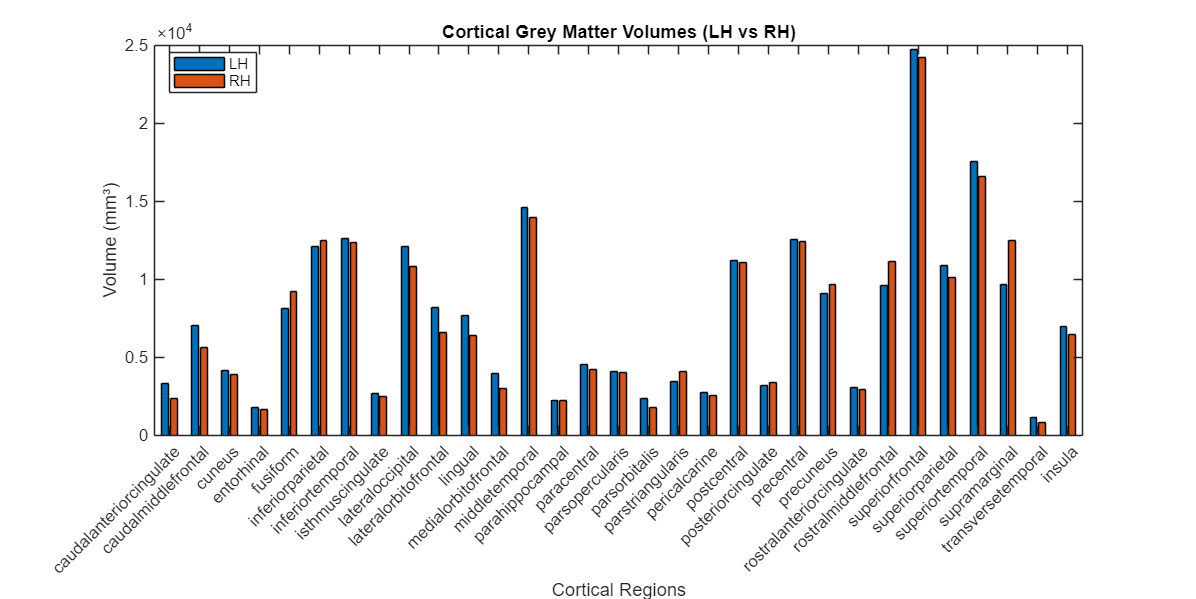

Total LH Grey Matter Volume: 237135.00 mm³


Total RH Grey Matter Volume: 230705.00 mm³


[~, p_val] = ttest(lhGrayVols, rhGrayVols);
fprintf('Paired t-test p-value: %.4f\n', p_val);

Ah, unfortunately, seems like the difference between the LH and RH grey matter is not statistically significant!

This is one way to compare across participants based on the grey matter volumetric data. Imagine how many different things you can do now with different ROIs, combined with demographic variables, and maybe across time as well! Let's start the Challenge Question of the day to find out more about our strucutral MRI dataset :)